Load equations and symbols from file

load symbols.mat
load CoreEquations.mat
load DesignParameters.mat

Calculate torque requirements for different movements

%Stage 1: Lifting against step from ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol1 = mysolver(Eqns);
sol1.T_z

$$ans = 1.0322143166704892953333203258087$$

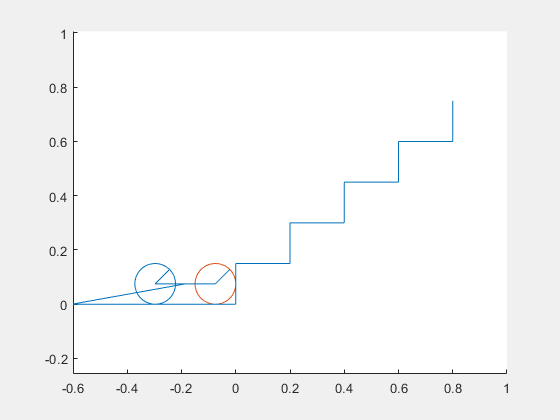

%Draw positions
drawfigure(sol1);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    s62 == rw; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

[sol2, unsolved] = mysolver(Eqns, 1);
sol2.T_z

$$ans = 0.59427615842169444086761247965204$$

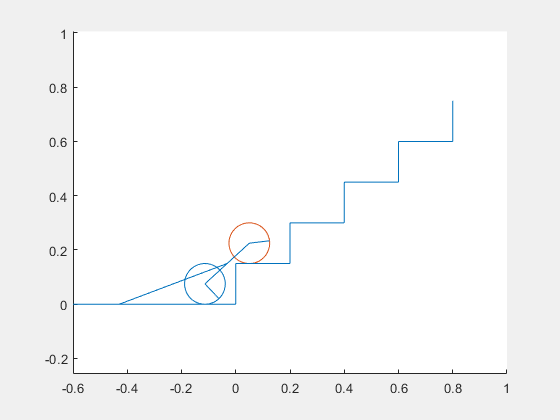

drawfigure(sol2);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z
drawfigure(sol3);

%Stage 1: Lifting against step from first step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    pi/2 < t73; t73 < pi;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z
drawfigure(sol3);

%Stage 6: Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    s62 == rw+step_height; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol4 = mysolver(Eqns);
sol4.T_z
drawfigure(sol4);

%Stage 6:Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol5 = mysolver(Eqns);
sol5.T_z
drawfigure(sol5);

%Stage 4:Lifting against step from second step with tail on first step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
sol6 = mysolver(Eqns);
sol6.T_z
drawfigure(sol6);

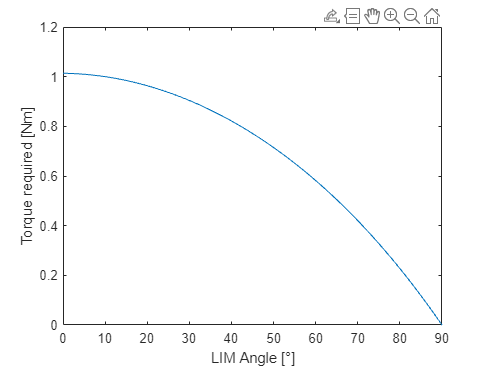

%Test stall torques across stage 1 movement
Eqns=[

    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)
solutions2 = []
for i = linspace(0, pi/2, 100)
    solutions1 = [solutions1; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
end

for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    thetarange(i) =solutions1(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 3 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
      C_friction7: 0.0
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react71: 0.0
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          N_idler: 33.0
         N_planet: 16.0
            N_sun: 50.0
              a13: 0.0
              a23: 0.0
              a33: 0.0
              a43: 0.0
              a52: 0.0
              a53: 0.0
              a62: 0.0
              a63: 0.0
              a73: 0.0
              f23: 0.0
              f33: 0.0
              f43: 

solutions3 = []


solutions =

     []



for i = linspace(-0.74188086214972967258453186960347, 0, 100)
    solutions3 = [solutions3; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
    solutions3(end).T_z
end

$$ans = 0.59427615842169442243622839204257$$

$$ans = 0.59882667916644271599914369907608$$

$$ans = 0.60336375661458306317007689976711$$

$$ans = 0.60788737669556362847383062951007$$

$$ans = 0.61239752356750695292798021924761$$

$$ans = 0.61689417961185609999567444993772$$

$$ans = 0.6213773254279426827586061278685$$

$$ans = 0.6258469398274767601652435672342$$

$$ans = 0.63030299982896285052779251172939$$

$$ans = 0.63474548065204204382286135145831$$

$$ans = 0.6391743557117643640980692649095$$

$$ans = 0.64358959661279181690347646866426$$

$$ans = 0.64799117314353493216022024957911$$

$$ans = 0.65237905327022506715540242235211$$

$$ans = 0.65675320313092426782756862131754$$

$$ans = 0.66111358702947448421994130952366$$

$$ans = 0.66546016742938838369135342957902$$

$$ans = 0.66979290494768450421919776761918$$

$$ans = 0.67411175834866716288465559271102$$

$$ans = 0.67841668453765513187189317519151$$

$$ans = 0.68270763855465903448012849889026$$

$$ans = 0.68698457356801144125851621498468$$

$$ans = 0.69124744086795005267081172211747$$

$$ans = 0.69549618986015664650306683981244$$

$$ans = 0.69973076805925393594214092918913$$

$$ans = 0.70395112108226202834813735130404$$

$$ans = 0.70815719264201616650596771399702$$

$$ans = 0.71234892454054785881742438365517$$

$$ans = 0.71652625666243197672274415763811$$

$$ans = 0.72068912696810014355758314791414$$

$$ans = 0.7248374714871241972292422198136$$

$$ans = 0.7289712243114695822455306311961$$

$$ans = 0.73309031758872239579681308132915$$

$$ans = 0.73719468151529033385393576731875$$

$$ans = 0.74128424432957994575727998936736$$

$$ans = 0.74535893230515231619955742144675$$

$$ans = 0.74941866974385801847861161739013$$

$$ans = 0.75346337896895360777924288116954$$

$$ans = 0.7574929803182010330898684997918$$

$$ans = 0.76150739213695175749023555957637$$

$$ans = 0.76550653077121667533492543386163$$

$$ans = 0.76949031056072391151649185029418$$

$$ans = 0.77345864383196549153148841760528$$

$$ans = 0.77741144089123444316484296403649$$

$$ans = 0.78134861001765362205176198671319$$

$$ans = 0.78527005745619751965743923411456$$

$$ans = 0.78917568741070824404587259159452$$

$$ans = 0.79306540203690676208720094188479$$

$$ans = 0.79693910143540064375937032371275$$

$$ans = 0.80079668364468866070827739281448$$

$$ans = 0.80463804463416408410251877755615$$

$$ans = 0.80846307829711661799219228279926$$

$$ans = 0.81227167644373384464185080285094$$

$$ans = 0.81606372879410291596327443496888$$

$$ans = 0.81983912297121313269279653381323$$

$$ans = 0.82359774449395889632561146800349$$

$$ans = 0.82733947677014438292054973037763$$

$$ans = 0.83106420108948882488268671269017$$

$$ans = 0.83477179661663345789259884756451$$

$$ans = 0.83846214038414908537363475140788$$

$$ans = 0.84213510728554386626357274303601$$

$$ans = 0.84579057006827148870137249505208$$

$$ans = 0.84942839932673820296320465728841$$

$$ans = 0.85304846349530795927376401929194$$

$$ans = 0.85665062884130465841439016601282$$

$$ans = 0.86023475945801032795415194209953$$

$$ans = 0.86380071725765688006508974021819$$

$$ans = 0.86734836196441036557512790681116$$

$$ans = 0.87087755110734544387291567800746$$

$$ans = 0.87438814001340750417361322723077$$

$$ans = 0.87787998180035996405312383479385$$

$$ans = 0.8813529273697136112517942073315$$

$$ans = 0.88480682539963547302858316396593$$

$$ans = 0.88824152233783233618700932968222$$

$$ans = 0.8916568623944066082298280502666$$

$$ans = 0.89505268753467862017580673532151$$

$$ans = 0.89842883747197231112622046808299$$

$$ans = 0.90178514966035799150763816414059$$

$$ans = 0.90512145928734725128910965695659$$

$$ans = 0.90843759926653462230697859697231$$

$$ans = 0.9117334002301784213860706197564$$

$$ans = 0.91500869052171549402250729979209$$

$$ans = 0.91826329618820097672993428105531$$

$$ans = 0.92149704097266680910767582164921$$

$$ans = 0.92470974630638906591425971142759$$

$$ans = 0.92790123130105670447847971912428$$

$$ans = 0.93107131274083065039697230019636$$

$$ans = 0.93421980507428453074148509154925$$

$$ans = 0.93734652040621504873122927997141$$

$$ans = 0.94045126848931102808538042293841$$

$$ans = 0.94353385671566905314832720440537$$

$$ans = 0.94659409010814261096374879846061$$

$$ans = 0.94963177131151051760976354084534$$

$$ans = 0.95264670058345119211008210258564$$

$$ans = 0.95563867578530627232896603608807$$

$$ans = 0.9586074923726180989646752306608$$

$$ans = 0.96155294338542341745377002593257$$

$$ans = 0.96447481943828567534554755322237$$

$$ans = 0.96737290871004633075839745309046$$

$$ans = 0.97024699693327547752853529430384$$


for i = 1:length(solutions3)
    Trange(i) = solutions3(i).T_z;
    thetarange(i) =solutions3(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2

%Test stall torques across stage 4 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
       C_friction7: 0.0
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime71: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
          N_planet: 16.0
             N_sun: 50.0
               a11: 0.0
               a12: 0.0
               a13: 0.0
               a21: 0.0
               a22: 0.0
               a23: 0.0
               a31: 0.0
               a32: 0.0
            

solutions4 = []


solutions4 =

     []



for i = linspace(0, pi/2, 100)
    solutions4 = [solutions4; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
    solutions4(end).T_z
end

$$ans = 1.1800240054091087229654098586133$$

$$ans = 1.1870904064179750653418680798655$$

$$ans = 1.1939873134897476707817573493381$$

$$ans = 1.2007092903731445374446898182718$$

$$ans = 1.2072508165027813281785677530714$$

$$ans = 1.2136062923610119571230501393985$$

$$ans = 1.2197700447813159073075899514878$$

$$ans = 1.2257363321877830257946826012284$$

$$ans = 1.2314993497662715954056241884698$$

$$ans = 1.2370532345638031018642942793633$$

$$ans = 1.242392070513702820347841198464$$

$$ans = 1.2475098933848954156176110100507$$

$$ans = 1.252400695654616195109979527699$$

$$ans = 1.2570584313045991766051735351959$$

$$ans = 1.2614770205415510815008728348953$$

$$ans = 1.2656503544434146913977342420889$$

$$ans = 1.2695722995335652085267372841878$$

$$ans = 1.2732367022856693340796271674918$$

$$ans = 1.276637393562469159093408104871$$

$$ans = 1.2797681929922324744989002171603$$

$$ans = 1.2826229132870389096219714051329$$

$$ans = 1.2851953645074488448822108957556$$

$$ans = 1.2874793582784309922684374972148$$

$$ans = 1.2894687119617067619921411407116$$

$$ans = 1.2911572527899070455979899008112$$

$$ans = 1.2925388219681319589769658483798$$

$$ans = 1.2936072787486585847014575296266$$

$$ans = 1.2943565044846580473280724353884$$

$$ans = 1.294780406668863567344150947211$$

$$ans = 1.2948729229631776666088507086974$$

$$ans = 1.2946280252252215926932613024202$$

$$ans = 1.2940397235378153789799866851821$$

$$ans = 1.293102070247334768085249303009$$

$$ans = 1.2918091640168234097626417154192$$

$$ans = 1.2901551538996471071187545351574$$

$$ans = 1.2881342434393631192036859764305$$

$$ans = 1.2857406948013432067162514261318$$

$$ans = 1.2829688329415356801549484513253$$

$$ans = 1.2798130498175805003881283493475$$

$$ans = 1.2762678086473036888685269810516$$

$$ans = 1.2723276482194140027893748104394$$

$$ans = 1.2679871872610069717543276141515$$

$$ans = 1.26324112886624981119442818161$$

$$ans = 1.258084264990376144371345133928$$

$$ans = 1.252511481012862491665660433502$$

$$ans = 1.2465177603733896330551795504557$$

$$ans = 1.2400981892839116316957775623818$$

$$ans = 1.2332479615198638491530035084753$$

$$ans = 1.2259623832932389306462251476147$$

$$ans = 1.2182368782099466625402018372828$$

$$ans = 1.2100669923135499092632123814323$$

$$ans = 1.2014483992171345699153318714181$$

$$ans = 1.192376905324726653189951422666$$

$$ans = 1.1828484551433141081151675088998$$

$$ans = 1.17285913668616488894871917107$$

$$ans = 1.1624051869677557709591415533558$$

$$ans = 1.1514829975902385476348977184782$$

$$ans = 1.1400891204209712970786364101603$$

$$ans = 1.1282202733602322720044581639122$$

$$ans = 1.1158733461978125157577085868804$$

$$ans = 1.1030454065567504216083408995814$$

$$ans = 1.0897337059220270409690235879018$$

$$ans = 1.0759356857515849437189304143175$$

$$ans = 1.0616489836665658123426873801344$$

$$ans = 1.0468714397171827266942369939593$$

$$ans = 1.0316011027201523344453079850693$$

$$ans = 1.0158362366631099284610732178767$$

$$ans = 0.9995753271709170565421225039157$$

$$ans = 0.9828170880282469335330302840623$$

$$ans = 0.96556046775229795218548788286131$$

$$ans = 0.94780465620894042464319576078052$$

$$ans = 0.92954909126504685057829636236588$$

$$ans = 0.91079346546919211910569161504313$$

$$ans = 0.89153773275233783265445730623338$$

$$ans = 0.87178211513953522564134291503207$$

$$ans = 0.85152710946309488893774451257113$$

$$ans = 0.83077349406707977407892560577667$$

$$ans = 0.80952233549238193660816697533411$$

$$ans = 0.78777499513104451436527595028744$$

$$ans = 0.76553313583788998721245054294817$$

$$ans = 0.74279872848691543121481580068556$$

$$ans = 0.71957405845931700540031305077834$$

$$ans = 0.6958617320494111790662962811196$$

$$ans = 0.67166468277413125326952471084645$$

$$ans = 0.64698617757119672841080508692346$$

$$ans = 0.62182982287048234306775283373812$$

$$ans = 0.59619957052255562435832643819115$$

$$ans = 0.57009972356780915658660702870803$$

$$ans = 0.54353494182908924162340069516085$$

$$ans = 0.51651024731021907550453528302251$$

$$ans = 0.48903102938233501494108486741585$$

$$ans = 0.46110304973950209170356382140881$$

$$ans = 0.43273244710465290398634887969095$$

$$ans = 0.4039257416665057291567108831043$$

$$ans = 0.37468983922776661352978497983761$$

$$ans = 0.34503203504460983581770267527555$$

$$ans = 0.31496001733716511354318656868393$$

$$ans = 0.28448187045052188029127884054308$$

$$ans = 0.25360607764559459575076526093764$$

$$ans = 0.22234152349908206606819782574371$$

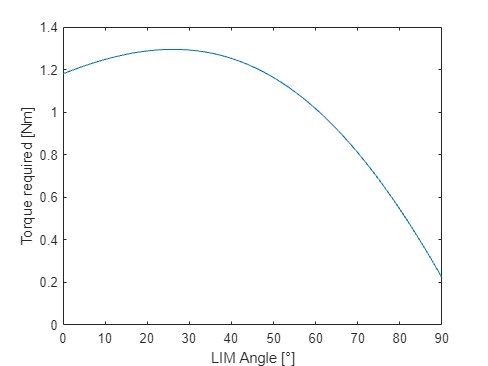


for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    thetarange(i) =solutions4(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 6 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
       C_friction7: 0.2
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
          N_planet: 16.0
             N_sun: 50.0
               a13: 0.0
               a23: 0.0
               a33: 0.0
               a43: 0.0
               a52: 0.0
               a53: 0.0
               a62: 0.0
               a63: 0.0
               a73: 0.0
            

solutions6 = []


solutions6 =

     []



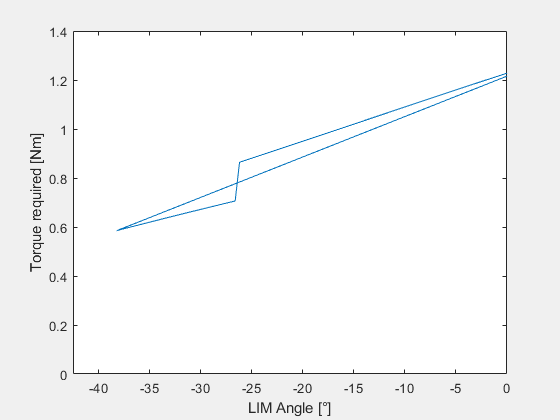

for i = linspace(-0.74188086214972967258453186960347, 0, 100)
    solutions6 = [solutions6; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
end

for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    thetarange(i) =solutions6(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off

Trange(end)/2

$$ans = 0.61396625142191406793275368260875$$

%Test stall torques with varying gear ratios
%remove certain parameters
reducedParameters = setdiff(DesignParameters, assignment_gears)

$$reducedParameters = \left(\begin{array}{c} I_{3}=\frac{7895689082865203}{590295810358705651712}\\ m_{4}=m_{3}\\ m_{6}=m_{5}\\ I_{2}=\frac{5072990516485623}{73786976294838206464}\\ m_{5}=\frac{61510981196073}{562949953421312}\\ m_{1}=\frac{4781504232814939}{18014398509481984}\\ I_{5}=\frac{4513494634395559}{36893488147419103232}\\ m_{2}=\frac{126477183527763}{1125899906842624}\\ m_{7}=\frac{7763401967589507}{18014398509481984}\\ I_{1}=\frac{3543923826346153}{2305843009213693952}\\ g_{2}=\frac{981}{100}\\ \mathrm{ratio7Weight}=\frac{1}{4}\\ {\mathrm{step}}_{\mathrm{width}}=\frac{1}{5}\\ {\mathrm{step}}_{\mathrm{start1}}=0\\ {\mathrm{step}}_{\mathrm{start2}}=0\\ {\mathrm{step}}_{\mathrm{start3}}=0\\ {\mathrm{step}}_{\mathrm{height}}=\frac{3}{20}\\ m_{3}=\frac{2720084835359431}{72057594037927936}\\ I_{4}=I_{3}\\ I_{6}=I_{5}\\ I_{7}=\frac{7562429506300977}{2305843009213693952} \end{array}\right)$$

%add back certain parameters, and add relation for gear separations to be
%based on gear ratios
new_assignment_gears = [%r3 == 0.027612244897959183673469387755102;
    l5_ab == 0.041+0.07;
    rw == 0.075; l7_ab == 0.425; 
    N_idler == 33; N_sun == 50; C_friction7 == 0.2;];

reducedEquations = setdiff(Core_equations, eqns_radius)


new_eqns_radius = [r2==separation23*N_sun/(N_sun+N_idler)
    r3==separation35*N_idler/(N_planet+N_idler)
    r3==separation23*N_idler/(N_idler+N_sun)
    r4==r3
    r5==separation35*N_planet/(N_planet+N_idler)
    r6==r5];

Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    reducedEquations; new_eqns_radius; reducedParameters; new_assignment_gears
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
       C_friction7: 0.2
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
             N_sun: 50.0
               a11: 0.0
               a12: 0.0
               a13: 0.0
               a21: 0.0
               a22: 0.0
               a23: 0.0
               a31: 0.0
               a32: 0.0
               a33: 0.0
               a41: 0.0
             

solutionsGR = []


solutionsGR =

     []



T_max = []


T_max =

     []



for j = 1:60
    Trange = []
    theta=linspace(0.4, 0.5, 10)
    [sol2, unsolved2]= mysolver([unsolved; N_planet == j], 0, sol);
    for i = 1:length(theta)
        solutionsGR = [solutionsGR; mysolver([unsolved2; t13 == theta(i)], 1, sol2)];
        Trange(i) = solutionsGR(i).T_z;
    end
    j
    [Tmax(j),idx] = max(Trange);
    thetarange(j) =solutionsGR(idx).t13*180/pi
    T_max
end


Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 1


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 2


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 3


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 4


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 5


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 6


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 7


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 8


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 9


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 10


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 11


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 12


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 13


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 14


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 15


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 16


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 17


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 18


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 19


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 20


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 21


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 22


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 23


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 24


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 25


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 26


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 27


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 28


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 29


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 30


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 31


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 32


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 33


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 34


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 35


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 36


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 37


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 38


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 39


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 40


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 41


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 42


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 43


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 44


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 45


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 46


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 47


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 48


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 49


T_max =

     []




Trange =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 50


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 51


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 52


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 53


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 54


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 55


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 56


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 57


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 58


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 59


T_max =

     []




Trange =

     []



theta = 1×10
    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 60


T_max =

     []



sol1.separation23

$$ans = 0.07$$

Create an animation by using the Runge Kutta method for discrete ODE solution

%Motor torque is not constant, create function to determine motor torque
%based on speed and voltage
motor_stallTorque = 6; % Nm
motor_NLSpeed = 0.6; %rad/s
syms speed stallTorque voltage 
eqns_motor = [
    speed == tv23;
    T_z == 2*motor_stallTorque*(voltage/12.0-speed/motor_NLSpeed)
    stallTorque == motor_stallTorque*(voltage/12.0)]

%Incomplete solution for movement1
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; eqns_motor; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set Motor voltage 
    stallTorque == 6;
    ];

[sol, unsolved] = mysolver(Eqns, 0);

Eqns=[unsolved;
    t13 == 0; t23 ==0 
    tv13 == 0; tv23 == 0;
    ]; 
[sol2, unsolved2] = mysolver(Eqns, 1, sol)


%Start calculations
framesol = []
frameeqs = unsolved
Step_Value = 0.005;
t_beg = 0;
t_end = 10;
t_intial=0;
u_intial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;




for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i); %t13
    up2=u(2,i); %t23
    up3=u(3,i); %tv13
    up4=u(4,i); %tv23
    framesol = [framesol; mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4;], 1)];
    k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], 1);
    k2 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], 1);
    k3 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], 1);
    k4 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
    i
end

f = fieldnames(sol)
nframes = length(framesol)
for i = 1:length(f)
    for j = 1:nframes
        framesol(j).(f{i}) = sol.(f{i});
    end
end

F(length(framesol)) = struct('cdata',[],'colormap',[]);
for j=1:length(framesol)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(framesol(j).s61, framesol(j).s62, framesol(j).rw);
    line([framesol(j).s61,framesol(j).s61+framesol(j).rw*cos(-framesol(j).t63+pi/4)],[framesol(j).s62,framesol(j).s62+framesol(j).rw*sin(-framesol(j).t63+pi/4)])
    
    circle(framesol(j).s51, framesol(j).s52, framesol(j).rw);
    line([framesol(j).s51,framesol(j).s51+framesol(j).rw*cos(-framesol(j).t53+pi/4)],[framesol(j).s52,framesol(j).s52+framesol(j).rw*sin(-framesol(j).t53+pi/4)])
    
    %frame
    line([framesol(j).s51,framesol(j).s61],[framesol(j).s52,framesol(j).s62])
    
    %Tail
    line([framesol(j).s11,framesol(j).s7End1],[framesol(j).s12,framesol(j).s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [framesol(j).step_start1-10; framesol(j).step_start2];
    for i= 1:5
        corner(:,2*i) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i-1)];
        corner(:,2*i+1) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;



movie(fig, F, 1, 1/h);



f=figure('visible','on');
hold on;
%wheels
circle(sol.s61, sol.s62, sol.rw);
line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])

circle(sol.s51, sol.s52, sol.rw);
line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])

%frame
line([sol.s51,sol.s61],[sol.s52,sol.s62])

%Tail
line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])

axis equal;
xlim([-0.6,1])
%ylim([-0.1, 0.5])
%step
corner(:,1) = [sol.step_start1-10; sol.step_start2];
for i= 1:5
    corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
    corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
end
line(corner(1,:), corner(2,:))
% line([sol.step_start1-10, sol.step_start1], [sol.step_start2,sol.step_start2])
% line([sol.step_start1, sol.step_start1], [sol.step_start2, sol.step_start2+ sol.step_height])
% line([sol.step_start1, sol.step_start1+sol.step_width], [sol.step_height, sol.step_height])
hold off;



function f = drawfigure(sol)
    f=figure('visible','on');
    hold on;
    %wheels
    circle(sol.s61, sol.s62, sol.rw);
    line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
    
    circle(sol.s51, sol.s52, sol.rw);
    line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
    
    %frame
    line([sol.s51,sol.s61],[sol.s52,sol.s62])
    
    %Tail
    line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [sol.step_start1-10; sol.step_start2];
    for i= 1:5
        corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
        corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
end

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end